clc, clear all

xs= 300;
zs= 500;
xr= 1300;
zr= 100;
dt = 0.001;

seconds = 1;
bandwidth =  500;
fs = 1/dt;
deep = 3000;

h = deep;
j = 8;
c = 1450;

% Time definitions

dt = 1/fs;
t = [-0.2:dt:seconds];
signal = sinc(bandwidth.*t)'

signal =     0.0000
   -0.0032
   -0.0000
    0.0032
   -0.0000
   -0.0033
    0.0000
    0.0033
   -0.0000
   -0.0033


r_t = greens(signal,fs,xs,zs,xr,zr,j,h, c)

r_t = 	1.0e+-4 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0


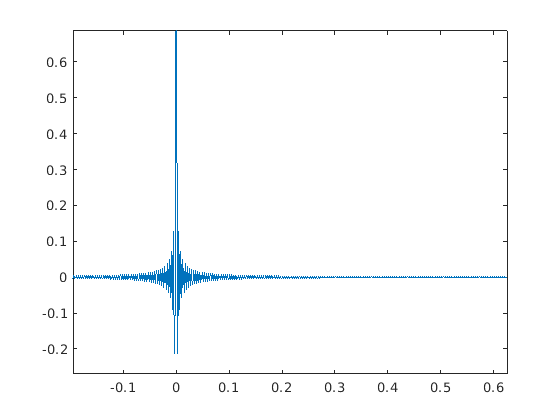


plot(t,signal)

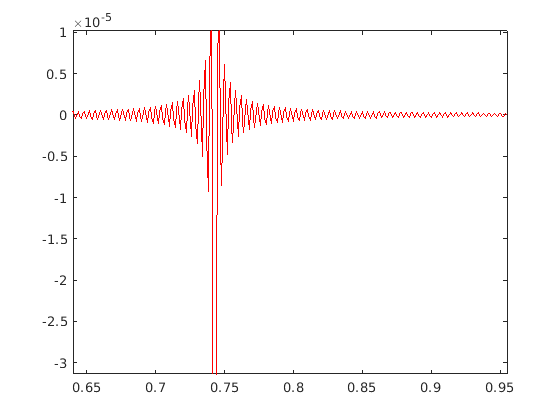

plot(t,r_t, 'r')

function r_t = greens(signal,fs,xs,zs,xr,zr,j,h, c)

    r_t = 0;
    
    for i =-j:j
        
        if mod(j,2) == 0  
        
            r_j = sqrt((xr-xs)^2 + (zr-zs + i * h)^2);
            e_j = 1;
        else   
            r_j = sqrt((xr-xs)^2 + (zr+zs - (i +1) * h)^2);
            e_j = -1;
        end
        
        delay = r_j/c;
        s_t = delayseq(signal,delay,fs);
        coeff = e_j/(4*pi*r_j);
        
        r_t = r_t + (coeff.* s_t);
        
    end
    
    r_t = -r_t;
       
    

end
